# Project “Vessel Detection in Endoscopic Data”

clc;
close all;
clear;

## load image

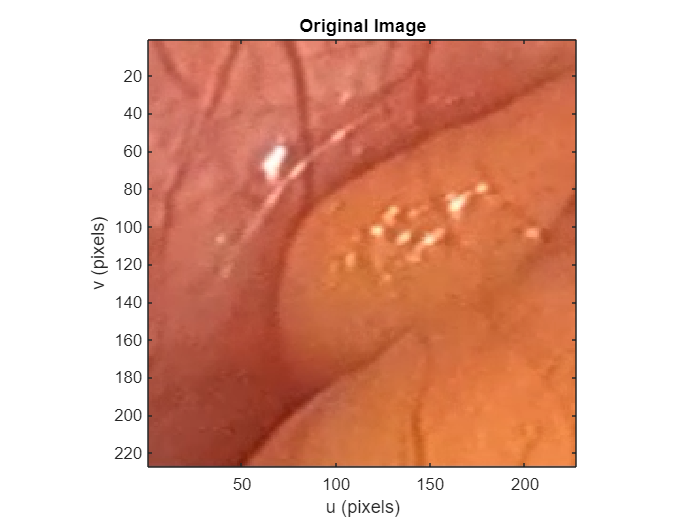

path = fullfile("images_endovideo","random","frame_left32819.png");
% path = fullfile("images_endovideo","fat","frame_left22812.png");
img = iread(path, 'uint8');
figure;
idisp(img, 'here', 'square');
title('Original Image');

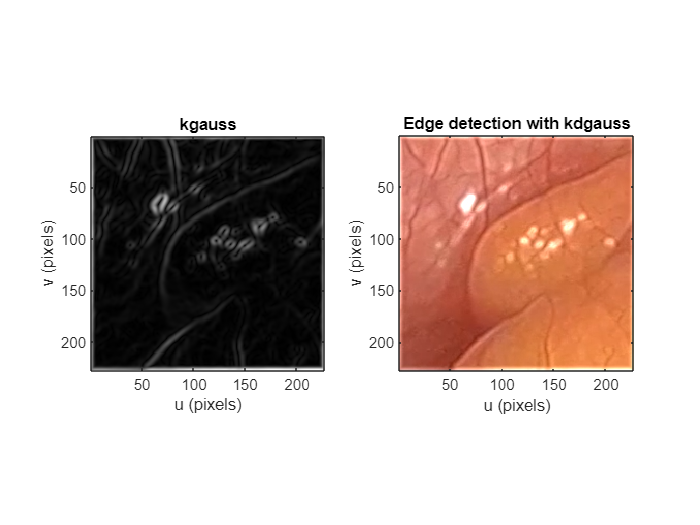

% Gradientenfilter anwenden
G = kdgauss(2) ./ 2^2;
[Igu, Igv] = isobel(img, G);
Imag2 = sqrt(Igu.^2 + Igv.^2);

% Normalisiere die Kanten
Imag2 = Imag2 ./ max(Imag2(:));

% Verstärke die Kanten
edge_strength = 0.55; % Anpassen des Verstärkungsfaktors
enhanced_img = im2double(img) + edge_strength * Imag2;

% Begrenze den Wertebereich auf [0, 1]
enhanced_img = max(min(enhanced_img, 1), 0);

figure;
subplot(121);
idisp(Imag2, 'here', 'square');
title('kgauss');
subplot(122);
idisp(enhanced_img, 'here', 'square');
title('Edge detection with kdgauss');

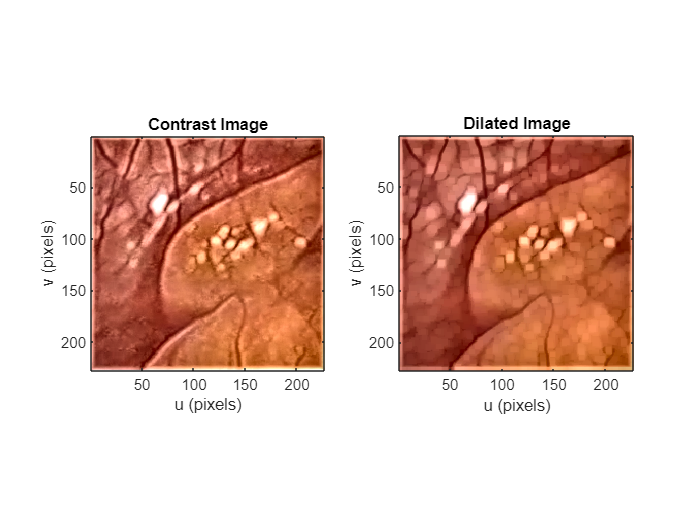

%% Kontrasterhöhung
shadow_lab = rgb2lab(enhanced_img);
L = shadow_lab(:,:,1)/100;

img_contrast = shadow_lab;
img_contrast(:,:,1) = adapthisteq(L)*100;
img_contrast = lab2rgb(img_contrast);

%% Erosion und Dilatation
se = strel('disk', 3);
img_eroded = imerode(img_contrast, se);
img_dilated = imdilate(img_eroded, se);

figure;
subplot(121)
idisp(img_contrast, 'here', 'square');
title('Contrast Image');
subplot(122)
idisp(img_dilated, 'here', 'square');
title('Dilated Image');

%% Segmentation
rng('default');  % Setzen Sie den Zufallszahlengenerator auf den Standardwert
[cls, cxy] = colorkmeans(img_dilated, 4);

 1:      0.5307       0.435      0.5938      0.4923 
 2:      0.3682      0.3577      0.3532      0.3716 


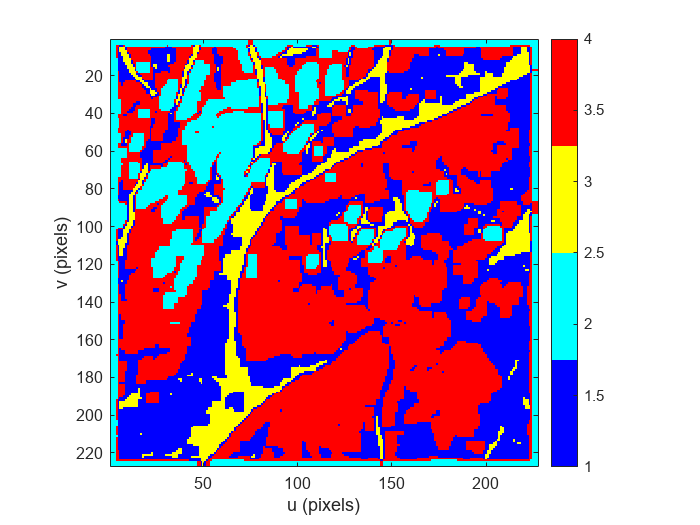

figure()
idisp(cls, 'here','colormap', 'Jet(4)', 'bar')


% cls_i = (cls == 3);
cls_num = input('Bar number: ');
cls_i = (cls == cls_num);

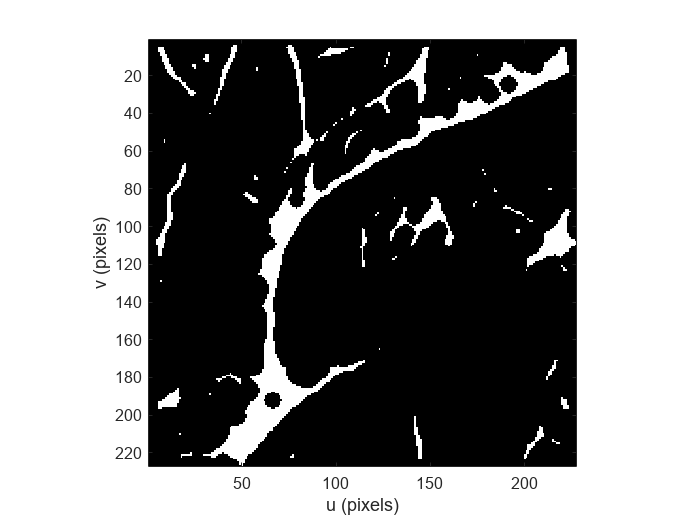

%% Morphology
se = kcircle(4);
closed = imbinarize(iclose(cls_i, se));
figure()
idisp(closed,'here', 'square')

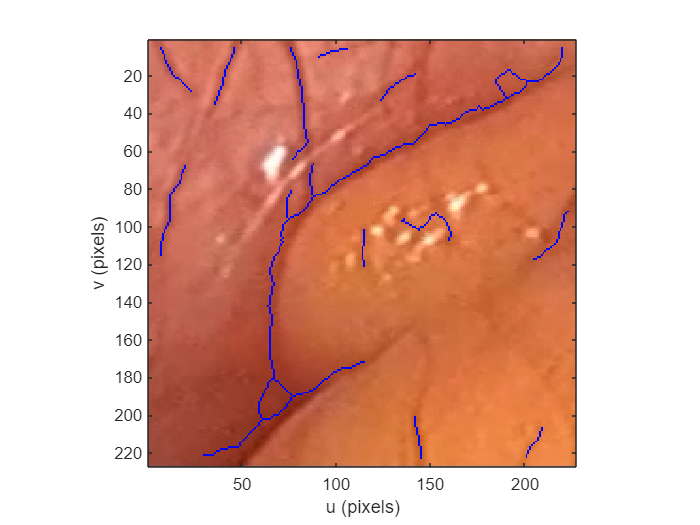

% clean = iopen(closed, se);
% figure()
% idisp(clean,'here', 'square')

out = bwskel(closed,'MinBranchLength',15);

figure()
idisp(labeloverlay(img, out, 'Transparency', 0),'here')